# Vector Data Analysis

© 2026 Moo K. Chung

University of Wisonsin-Madison.

Vector fields arise naturally in many medical imaging applications. Examples include deformation fields obtained from image registration, displacement fields in cardiac and respiratory motion analysis, diffusion-related directional fields, and surface vector fields describing anatomical shape variation. Such vector-valued measurements provide rich information about the magnitude and direction of local anatomical changes. However, vector fields estimated from imaging data can be highly sensitive to measurement noise, image preprocessing, numerical differentiation, and registration errors. This variability presents a particular challenge for population-level statistical inference, where noisy vector estimates and outliers can substantially influence group comparisons.

A simpler alternative is to represent the vector field through an underlying smooth scalar function that generates the field [1, 2]. Rather than performing statistical inference directly on a noisy vector field, we seek a scalar potential whose gradient explains the observed field. This transforms a vector-valued functional data inference problem into a simpler scalar-valued functional data inference problem.

References.

[1] Chung, M.K., Maccotta, L., Struck, A. 2026, [Poisson Flow of Cortical Folding in Juvenile Myoclonic Epilepsy](https://arxiv.org/pdf/2606.08404), arXiv:2606.08404 (longer journal version, under review in journal [Human Brain Mapping](https://onlinelibrary.wiley.com/page/journal/10970193/homepage/productinformation.html))

[2] Chung, M.K., Maccotta, L., Struck, A. 2026 [Poisson Flow Model of Cortical Folding Pattern](https://github.com/laplcebeltrami/poisson/blob/main/chung.2026.EMBC.poisson.pdf), IEEE Engineering in Medicine and Biology Conference (EMBC), pages 1-5 (shorter conference version)

## **Synthetic Vector Field**

We first generate a synthetic scalar function


$$Z(x,y)=x e^{-x^2-y^2}$$


on a regular two-dimensional grid. We then numerically compute its gradient


$$\nabla Z= \left( \frac{\partial Z}{\partial x}, \frac{\partial Z}{\partial y} \right).$$


The gradient defines a synthetic vector field in which each vector points in the direction of the greatest local increase of $Z$, while its magnitude represents the rate of change. The vector field is visualized using arrows.

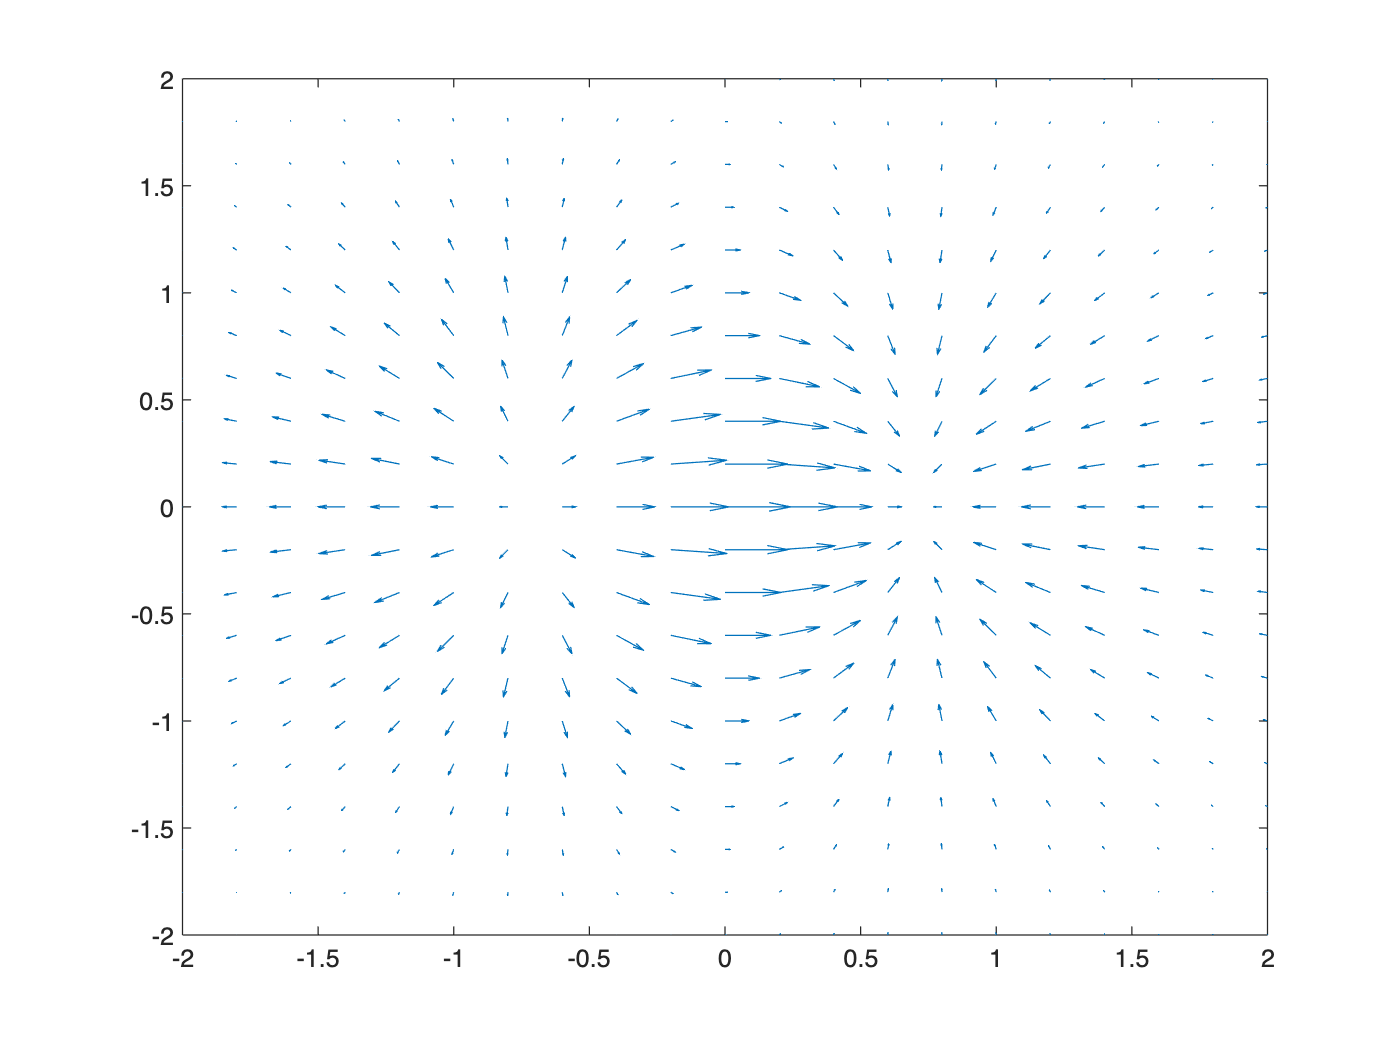

clear; close all;
spacing = 0.2;
x       = -2:spacing:2;
y       = -2:spacing:2;
[X, Y]  = meshgrid(x,y);
Z       = X .* exp(-X.^2 - Y.^2);
[DX,DY] = gradient(Z, spacing);
quiver(X, Y, DX, DY), axis([-2 2 -2 2])

## Contour Visualization

The contour plot displays the level curves of the scalar function $Z(x_1,x_2)$. Each contour represents a constant value

$Z(x_1,x_2)=c$.

The contour plot provides a two-dimensional representation of the shape of the scalar surface. Closely spaced contours indicate regions where $Z$ changes rapidly, whereas widely spaced contours indicate regions where $Z$ changes slowly. The gradient $\nabla Z$ is perpendicular to the contour lines and points toward increasing values of $Z$. Consequently, $-\nabla Z$ points toward decreasing values and defines the direction of the corresponding flow.

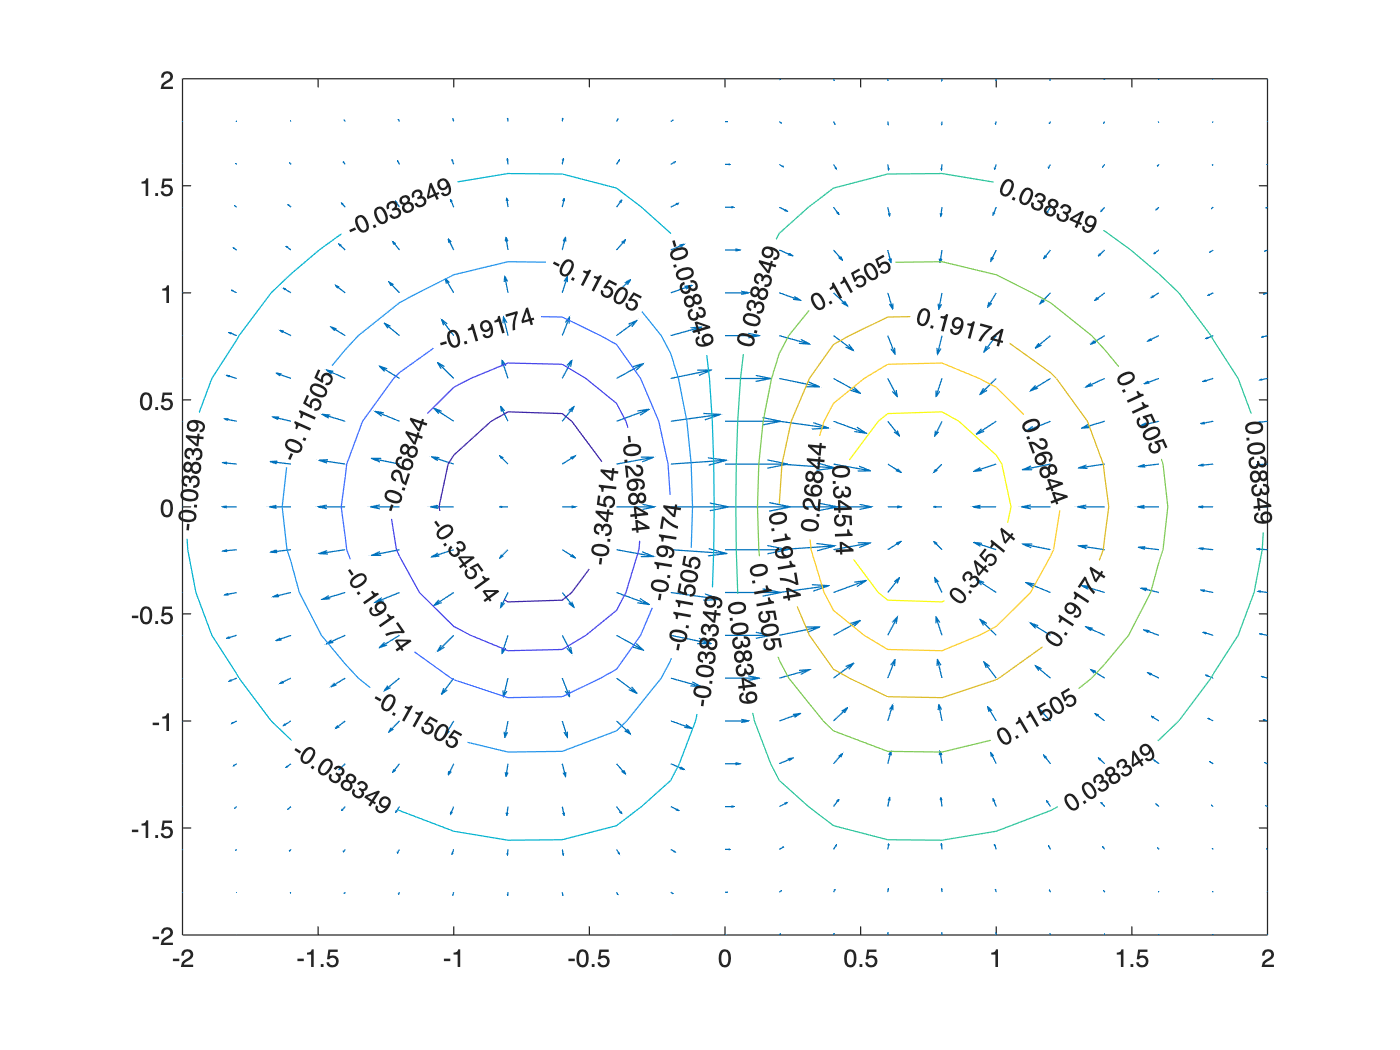

hold on;
level   = 10;
contour(X, Y, Z, level, 'ShowText', 'on')

## Stream Line Visualization

Given vector field $V=(V_1,V_2)$, we can estimate smooth streamline $\gamma(t)$ that generate the underlying field. 


$$\frac{d\gamma(t)}{dt}=V(\gamma(t))$$


We can have multiple solutions, and thus can genreate a familiy of stremlines $\gamma(t) = c$. Matlab solve for each $x$ and $y$ coordinates


$$\frac{dx}{dt}=V_1(x,y), \qquad \frac{dy}{dt}=V_2(x,y).$$


at each time step $\delta t$. 

 
$$\gamma_{j+1} = \gamma_j+\delta t\,V(\gamma_j).$$


If the time step is sufficently smooth, we obtain smooth trajectory that genrates the vector field.

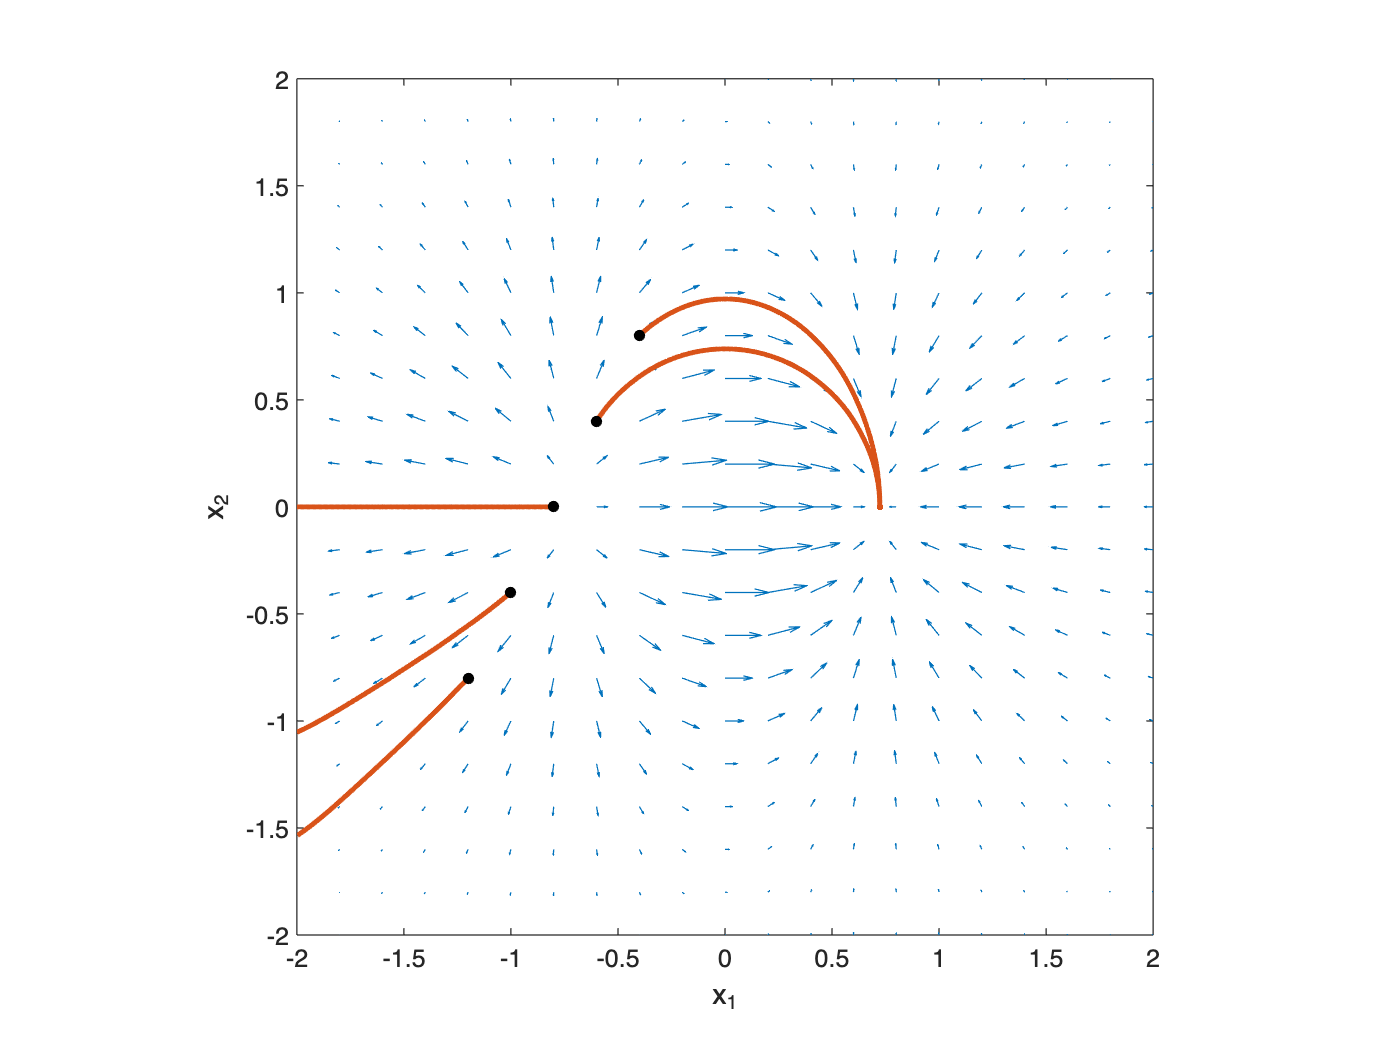


% Starting points for streamlines
% Starting points for streamlines
startX = [-1.2 -1.0 -0.8 -0.6 -0.4];
startY = [-0.8 -0.4  0.0  0.4  0.8];

% Compute streamlines
S = stream2(X,Y,DX,DY,startX,startY,[0.02 10000]);

% Visualization
figure

% Vector field
quiver(X,Y,DX,DY)
hold on

% Streamlines
h = streamline(S);
set(h,'LineWidth',2)

% Starting points
plot(startX,startY,'ko','MarkerFaceColor','k','MarkerSize',4)

axis equal
axis([-2 2 -2 2])
xlabel('x_1'); ylabel('x_2')

## Poission Equation

We are interested in estimating a smooth scalar potential $u$ from an observed vector field $V$. We assume the model


$$V(x)=-\nabla u(x)+\epsilon(x),$$


where $\epsilon$ is error functon. We estimate $u$ by


$$\widehat u=\arg\min_u \int \|V(x)+\nabla u(x)\|^2\,dx.$$


We can prove that the minimizer satisfies the Poisson equation [1]


$$\Delta\widehat u=-\nabla\cdot V  = - 
\frac{\partial V_1}{\partial x_1}
-
\frac{\partial V_2}{\partial x_2}.$$


where $\Delta=\frac{\partial^2}{\partial x_1^2}+\frac{\partial^2}{\partial x_2^2}\]$ is the  Laplacian and $\Delta \cdot$ is the divergence.

The solution is determined only up to a constant since


$$\Delta(\widehat u+c)=\Delta\widehat u.$$


Thus, an additional constraint is needed for uniqueness.

## Problems

- Compare the analytical gradient with the numerical gradient computed using Matlab function `gradient.m`.

- Implement Matlab’s `stream2.m` function from the ground up using only the defining equation for a streamline. 

- Show that the mininizer $\widehat u=\arg\min_u \int \|V(x)+\nabla u(x)\|^2\,dx$ satisfies the Poisson equation. 

- Given a traingle surface mesh in 3D, implement` stream3.m` function that computes and displays the streamline on the surface mesh.